# **Letter Classification**

## **Data Import**

traindata = readtable("Data\traindata.xlsx");
testdata = readtable("Data\testdata.xlsx");

testfiles = readcell("Data\testFiles.xlsx");

# **Models Evaluation**

## kNN

### Simple kNN

kNNmodel = fitcknn(traindata,"Character");

% Model Evaluation
loss(kNNmodel,testdata)

ans = 0.2254

#### Weighted kNN

kNNmodel = fitcknn(traindata, "Character",'Distance', 'Cityblock', 'Exponent', [], ...
    'NumNeighbors', 6, 'DistanceWeight', 'SquaredInverse', 'Standardize', true);

% Model Evaluation
loss(kNNmodel,testdata)

ans = 0.1511

## Bagged Trees

rng(123)
TBmodel = fitcensemble(traindata,"Character","Method","Bag","Learners","tree","NumLearningCycles",30);

% Model Evaluation
loss(TBmodel,testdata)

ans = 0.1407

## Neural Networks

#### Wide Neural Network

modelNN = fitcnet(traindata,"Character",'LayerSizes', 170,'Activations', 'relu', ...
    'Lambda',0,'IterationLimit', 1000,'Standardize', true);

% Model Evaluation
loss(modelNN,testdata)

ans = 0.1558

## SVM

#### Linear SVM

template = templateSVM('KernelFunction', 'linear', 'PolynomialOrder', [], ...
    'KernelScale', 'auto', 'BoxConstraint', 1, 'Standardize', true);

linearSVM = fitcecoc(traindata,"Character",'Learners',template,'Coding','onevsone');

% Model Evaluation
loss(linearSVM,testdata)

ans = 0.1505

#### Quadratic SVM

template = templateSVM('KernelFunction','polynomial','PolynomialOrder',2, ...
    'KernelScale','auto','BoxConstraint',1,'Standardize',true);

quadraticSVM = fitcecoc(traindata,"Character",'Learners',template,'Coding','onevsone');

% Model Evaluation
loss(quadraticSVM,testdata)

ans = 0.1132

#### Cubic SVM

template = templateSVM('KernelFunction','polynomial','PolynomialOrder',3, ...
    'KernelScale','auto','BoxConstraint', 1,'Standardize', true);

cubicSVM = fitcecoc(traindata,"Character",'Learners',template,'Coding','onevsone');

% Model Evaluation
loss(cubicSVM,testdata)

ans = 0.1146

## Best Models Evaluation

% Testing; best models under that category
 model = quadraticSVM

model =   ClassificationECOC
           PredictorNames: {1×25 cell}
             ResponseName: 'Character'
    CategoricalPredictors: []
               ClassNames: {'A'  'B'  'C'  'D'  'E'  'F'  'G'  'H'  'I'  'J'  'K'  'L'  'M'  'N'  'O'  'P'  'Q'  'R'  'S'  'T'  'U'  'V'  'W'  'X'  'Y'  'Z'}
           ScoreTransform: 'none'
           BinaryLearners: {325×1 cell}
               CodingName: 'onevsone'


  Properties, Methods



predLetter = predict(model, testdata);

% accuracy
accurate = nnz(predLetter == string(testdata.Character)) / numel(testdata.Character)

accurate = 0.8822

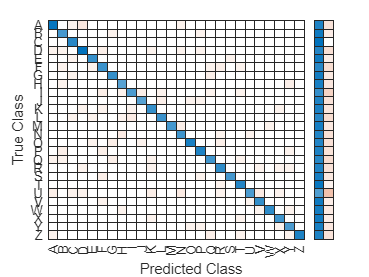


% Confusion Matrix
confusionchart(testdata.Character,predLetter, "RowSummary","row-normalized");

# **Best Result : Quadratic SVM => 88.22%**

% best prediction on test cases by Quadratic SVM
predLetter = predict(quadraticSVM, testdata);

accuracy = nnz(predLetter == string(testdata.Character)) / numel(testdata.Character);

confusionchart(testdata.Character,predLetter, "RowSummary","row-normalized");

## Analyze misclassifications

#### Confusion matrix

cm = confusionmat(testdata.Character,predLetter);

% Split into correct and incorrect classifications
yes = diag(cm);
no = cm - diag(yes);

#### Misclassification rate for each letter

misratebyletter = sum(no,2) ./ sum(cm,2);

#### Table with letter names and misclassification rate

letters = categories(categorical(traindata.Character));
misratebyletter = table(letters,misratebyletter,'VariableNames',["Letter","MisClassRate"]);

% Sort by worst misclassification
misratebyletter = sortrows(misratebyletter,"MisClassRate","descend")

misratebyletter = 26×2 table
    Letter    MisClassRate
    ______    ____________

    {'U'}       0.32558   
    {'P'}       0.21622   
    {'J'}       0.16216   
    {'B'}       0.15789   
    {'W'}       0.15789   
    {'I'}       0.14286   
    {'T'}       0.13889   
    {'R'}       0.13636   
    {'D'}       0.12903   
    {'K'}       0.12821   
    {'V'}       0.12766   
    {'F'}       0.11905   
    {'H'}       0.11905   
    {'Q'}       0.10811   
    {'Z'}           0.1   
    {'N'}       0.09375   


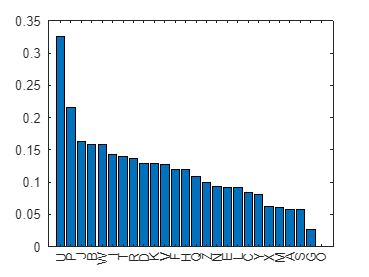

bar(misratebyletter.MisClassRate)
xticks(1:26)
xticklabels(misratebyletter.Letter)

#### Individual misclassification

letter = "U";

#### True class that were misclassified as something else

misclassidx = (string(testdata.Character) == letter) & (predLetter ~= string(testdata.Character));

#### Table of the misclassified observations, with the predicted letter

badpred = testdata(misclassidx,:);
badpred.Prediction = predLetter(misclassidx);

### Plot

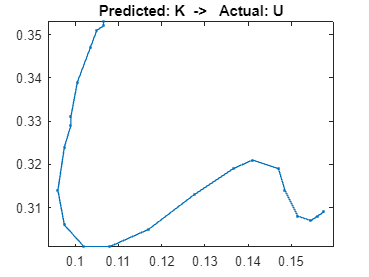

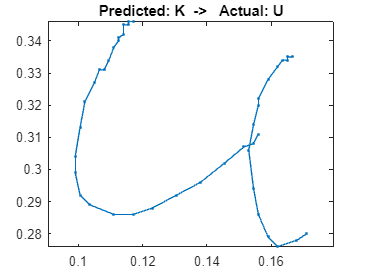

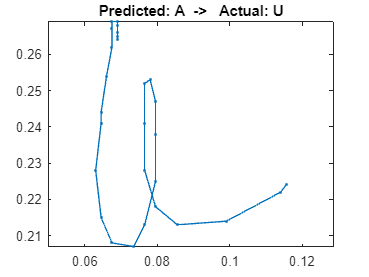

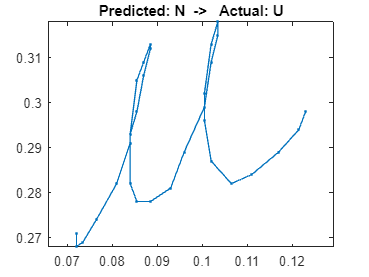

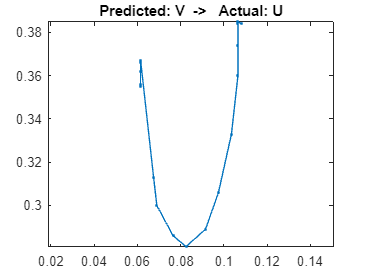

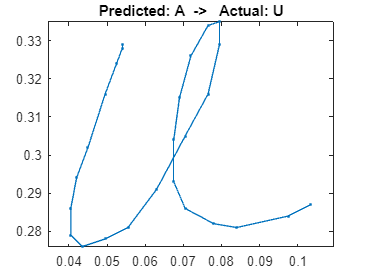

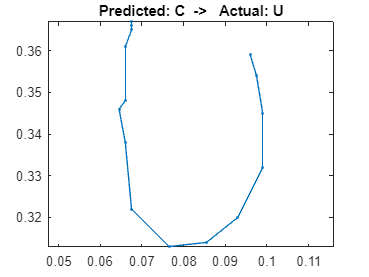

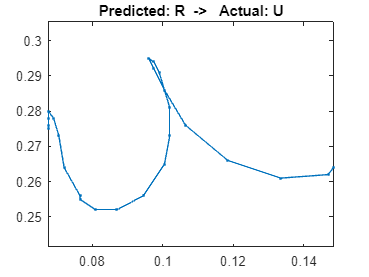

badfiles = testfiles(misclassidx);

for k = 1:numel(badfiles)
    badletter = readtable("Files"+filesep+badfiles(k));
    figure
    plot(1.5*badletter.X,badletter.Y,".-")
    title("Predicted: "+string(badpred.Prediction(k))+"  ->   Actual: "+letter)
    axis equal
end